# 第 4 章  数值计算

- **数值计算**在**科研**和**工程**中的应用比符号计算**更为广泛**。

- MATLAB正是凭借其**卓越的数值计算能力**而著称。

## 4.1   数值微积分

4.1.1   **近似数值极限及导数**

- MATLAB数值计算中，没有专门的求极限和导数的指令

                原因是数值精度有限，不能表示无穷小量，不能准确描述一个数的邻域

- 高度重视有限精度浮点表示的离散本质，

                切勿贸然编写求极限和求导的数组计算程序

                需要求数值近似导数时，自变量的增量要大于原始相对精度的10倍以上

- 解算极值、积分和微分方程等数值问题时，

                尽量使用现成指令，严格遵循指令的使用规则

- MATLAB数值计算中，没有提供求导和求极限指令，

                但提供了与求导概念有关的求差分指令：

                `dx=diff(X)`                       **计算向量****X****的向前差分**

                `dx=diff(X,n)`                   **计算****X****的****n****阶向前差分，****diff(X,2)=diff(diff(X))**

                `dx=diff(X,n,dim)`            **计算****X****矩阵的****n****阶差分，****dim=1****按列计算差分**

**                                                        dim=2****按行计算差分，默认值****dim=1**

                `FX=gradient(F)`               求一元（函数）梯度

                `[FX,FY]=gradient(F)`      求二元（函数）梯度

**〖说明〗**

- 当X是向量时，dx = X(2:n) – X(1:n-1) ,    

                当X是矩阵时，dx = X(2:n,:) – X(1:n-1,:),   

                dx比X的长度少一个元素

- 求梯度时，当F是向量时，FX(1) = F(2) – F(1),  FX(end) = F(end) – F(end-1),  

                FX(2:end-1) = (F(3:end) – F(1:end-2))/2，

                梯度采用内点中心差分，FX的“长度”与F**相同**。

                当F是矩阵时，FX和FY是与F同样大小的矩阵。

                FX的每行给出F相应行元素间的“梯度”；

                FY的每列给出F相应列元素间的“梯度”。

【例4.1-1】设$f_{1}(x)=\frac{1-\cos 2 x}{x \sin x}, \quad f_{2}(x)=\frac{\sin x}{x}$

试用相对精度值eps替代理论0计算极限


$$L_{1}(0)=\lim _{x \rightarrow 0} f_{1}(x), \quad L_{2}(0)=\lim _{x \rightarrow 0} f_{2}(x)$$


% 不可信的“极限的数值近似计算”
x=eps;
L1=(1-cos(2*x))/(x*sin(x))    %不可信
L2=sin(x)/x,						  %恰好与理论值一致

% 可信的“极限的符号计算”
syms t
f1=(1-cos(2*t))/(t*sin(t));
f2=sin(t)/t;
Ls1=limit(f1,t,0)
Ls2=limit(f2,t,0) 

**〖说明〗**

- 理论分析表明：$f_{1}(x)=2 f_{2}(x)$, $L_{2}(0)=\lim _{x \rightarrow 0} f_{2}(x)=\lim _{x \rightarrow 0} \frac{\sin x}{x}=1$。

                用数值法近似计算的极限与理论不一致；

                借助符号计算所求的极限与理论值一致。

- **除非**数值近似法求的极限经过理论验证，否则**绝不要**借助数值法求取极限。

 【例4.1-2】已知$x=\sin (t)$，求该函数在区间$\left\lbrack 0,2\pi \text{ }\right\rbrack$中的**近似导函数**。

函数$y=f\left(x\right)$在点$x_0$处的**导数**


$$y'\vert_{x=x_0}=\lim_{\Delta x}\frac{\Delta y}{\Delta x}=\lim_{\Delta x \to 0} \frac{f(x_0+\Delta x)-f(x_0)}{\Delta x}$$


**结论**：自变量增量太小会照成∆y的许多高位有效数字消失，

导致精度急剧变差。自变量增量一定要适当取值。

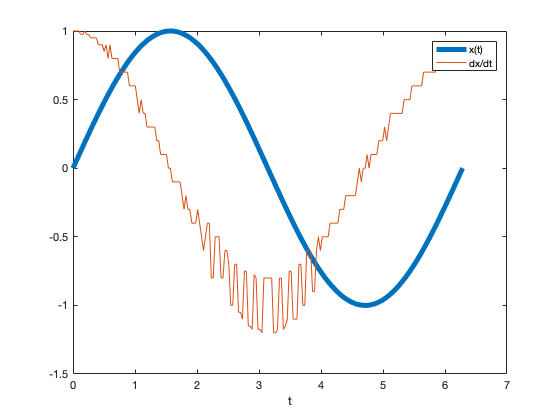

%自变量取值过小
d=pi/100;
t=0:d:2*pi;

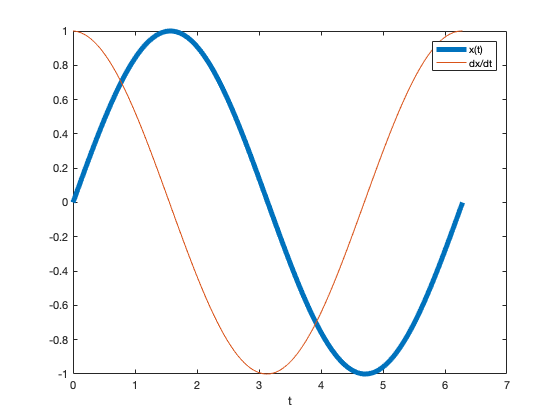

x=sin(t);
dt=5*eps;						
x_eps=sin(t+dt);          % 自变量的增量为5eps（太小）
dxdt_eps=(x_eps-x)/dt;	    % 近似数值导数
plot(t,x,'LineWidth',5)   % 画原函数图
hold on
plot(t,dxdt_eps)          % 画导函数图
hold off
legend('x(t)','dx/dt')
xlabel('t')  


% 自变量取值适当
x_d=sin(t+d);             
dxdt_d=(x_d-x)/d;			 %以d=pi/100为增量（合适）
plot(t,x,'LineWidth',5)
hold on
plot(t,dxdt_d)
hold off
legend('x(t)','dx/dt')
xlabel('t')     

【例4.1-3】已知$x=\sin (t)$，

采用diff和gradient计算该函数在区间$\left\lbrack 0,2\pi \text{ }\right\rbrack$中的近似导函数。

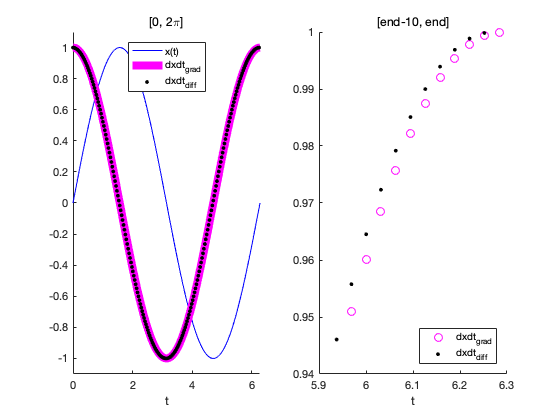

clf
d=pi/100;						
t=0:d:2*pi;
x=sin(t);
dxdt_diff=diff(x)/d;		
dxdt_grad=gradient(x)/d;	
subplot(1,2,1)     % 宏观上看，diff和gradient所求得近似导数大体相同
plot(t,x,'b')
hold on
plot(t,dxdt_grad,'m','LineWidth',8)
plot(t(1:end-1),dxdt_diff,'.k','MarkerSize',8)
axis([0,2*pi,-1.1,1.1])
title('[0, 2\pi]')
legend('x(t)','dxdt_{grad}','dxdt_{diff}','Location','North')
xlabel('t'),box off
hold off
subplot(1,2,2)
kk=(length(t)-10):length(t);      % 最后11个数据的下标
hold on
plot(t(kk),dxdt_grad(kk),'om','MarkerSize',8)     

% 微观上看，不仅数值上有差异，
plot(t(kk-1),dxdt_diff(kk-1),'.k','MarkerSize',8)
% 而且diff没有给出最后一点的导数。
title('[end-10, end]')
legend('dxdt_{grad}','dxdt_{diff}','Location','SouthEast')
xlabel('t'),box off
hold off 
clf

**4.1.2 ** **数值求和与近似数值积分**

**        Sx=sum(X)                **沿列方向求和

**        Scs=cumsum(X)       **沿列方向求累计和$Sx(k)=\sum_{i=1}^m X_{m\times n}(i,k)$

**        St=trapz(x,y)            **用梯形法沿列方向求函数y关于自变量x的积分

**        Sct=cumtrapz(x,y)   **用梯形法沿列方向求函数y关于自变量x的累计积分

**〖说明〗**	

- 若X是m×n数组，Sx是1×n，Scs是m×n数组；Scs仍是m×n数组

- Sct是一个与y同样大小的数组，$Sct(k)=\int_{x(1)}^{x(k)} Y(x)dx$

- 在对积分精度没有严格要求的场合，用trapz和cumtrapz比较方便，

                积分精度与与积分区间的分隔稀密程度有关

                无法预先设置欲求积分的精度，此外计算速度低且不能处理广义积分

【例题】

A=true(4,9)
B=sum(A)
B1=cumsum(A)

【例 4.1-4】求积分$S(x)=\int_0^{x/2} y(t) d(t)$，其中$y=0\ldotp 2+\mathrm{sin}\text{ }t$。

clear
d=pi/8;					
t=0:d:pi/2;				
y=0.2+sin(t);				
s=sum(y);					

sum求得积分   trapz求得积分


s_sa=d*s;					       % 矩形法

    1.5762    1.3013



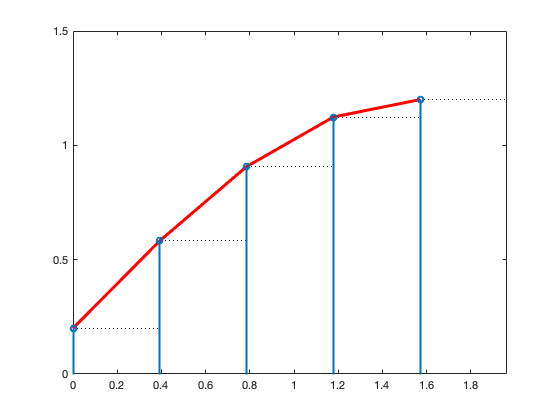

s_ta=d*trapz(y);			       % 
disp(['sum求得积分',blanks(3),'trapz求得积分'])
disp([s_sa, s_ta])
t2=[t,t(end)+d];					% 画阶梯图最后一个阶梯需要
y2=[y,nan];						   
stairs(t2,y2,':k')				% 画阶梯图
axis([0,pi/2+d,0,1.5])
hold on

plot(t,y,'r','LineWidth',3)	% 画trapz积分图
stem(t,y,'LineWidth',2);		% 画杆图
hold off  

**4.1.3 ****计算精度可控的数值积分**

- 近似数值积分trapz难以控制精度、不能处理广义积分且运算速度很慢。

                精度可控的数值积分可有效地克服这些缺点

- 在xmin到xmax区间上计算fun函数的精确积分指令：

**                q=integral(fun,xmin,xmax)**                               简单调用格式

**                q= integral(fun,xmin,xmax,****Name****,****Value****) **       复杂调用格式

〖说明〗

- 能处理广义积分和复数路径积分，计算精度高，速度更快。

- 被积函数fun是M码**匿名函数**、M函数文件的**函数句柄**

- 对标量型被积函数y=*f* (x)，x为1×n数组时，

                匿名函数和函数文件的输出y也应该是1×n数组

- 阵列型被积函数，如m×1阵列y=[f1(x),…,fm(x)]T，

               当x是标量时，y也应是m×1阵列

                此时输入量中必须含有‘Array Valued’选项，取值是true

- 上下积分限xmin和xmax，在实数领域可取有限和无限标量；

                在复数领域其实、虚部必须是有限量

                上下限至少有一个是复数时，将给出从xmin到xmax直线的路径积分

- 复杂调用格式中可选多个“**Name****,****Value**”选项对，见表4.1-1

- MATLABA还有二重和三重积分命令integral2和integral3

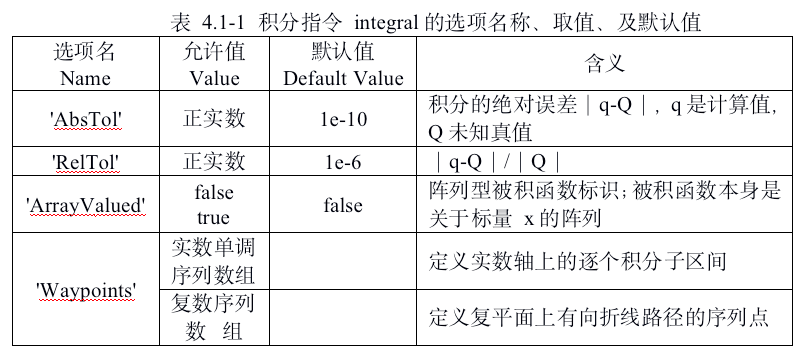

【例 4.1-5】在0≤x≤1之间，求两曲线$g_1 \left(x\right)=\frac{\text{ }1}{\sqrt[5]{x}}$和$g_2 \left(x\right)=x^5$所夹区域的面积

（1）绘图

clf
x=linspace(0.01,1.2,50);		% 生成50个元素的自变量
g1=x.^(-0.2);	g2=x.^5;				

xc0 = -8.4867

fc0 = -1.8621

exitflag = 1

plot(x,g1,'-r.',x,g2,'-b*')
axis([0,1.2,0,3])
legend('g_1(x)=1/x^{0.2}','g_2(x)=x^5','Location','North')
title('x位于[0,1]间的g_1(x)曲线与g_2(x)曲线所夹的区域') 

（2）采用标量型匿名函数计算积分

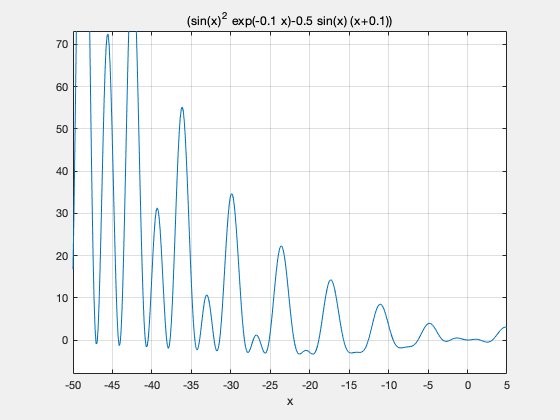

xx = -29.7869

yy = 34.4528

format long
G1=@(x)x.^-0.2;			% 匿名函数FH=@(arglist)expr
Q1=integral(G1,0,1)		% <9>

G2=@(x)x.^5;				% 匿名函数 
Q2=integral(G2,0,1)		% <11>
S12=Q1-Q2 				   % [0,1]区间的积分差<12>   

（3）采用阵列型匿名函数计算积分

G=@(x)x.^[-0.2;5];						 % 阵列型匿名函数 <13>
Q=integral(G,0,1,'ArrayValued',true)	%<14>
S=[1,-1]*Q  					          % 矩阵乘求差值 <15> 

（4）符号积分验算

syms t										%

函数最小值-3.34765发生在x=-19.60721处

Gsym=vpa(int(t.^[-0.2;5],0,1)); %得到量函数32位精度的积分值
Ssym=Gsym(1)-Gsym(2)				  %<17>   

【例 】求 $I = \int_0^1e^{-x^2}dx$。

syms x    采用符号计算
Isym=vpa(int(exp(-x^2),x,0,1))  % 给出32位精度的积分值

format long					     % 15位数字显示
d=0.001;x=0:d:1;
Itrapz=d*trapz(exp(-x.*x))    % 梯形法,默认绝对精度1e-10

format long
d=0.001;x=0:d:1;
G=@(x)exp(-x.*x)                    % 匿名函数
I_int=integral(G,0,1,'AbsTol',1e-8) % 控制绝对精度达1e-8

**4.1.4 **  **函数极值的数值求解**

**            [x,fval,exitflag,output]=fminbnd(****fun****,** **x1,** **x2****, options****)**       

                                                    求一元函数在区间（x1, x2）中的极小值

**            [x,fval,exitflag,output]=fminsearch(fun, x0, options) **      求多元函数极值点

〖说明〗

- fun是待解目标函数，可是字符串、匿名函数和M函数文件的函数句柄等

-  fminsearch中被优化的目标函数fun中的多元自变量，

                应采用单一变量名的向量形式表达，如x(1), x(2),…, x(N)

                minsearch的第二个输入量x0可以是一个搜索起点的向量

                或一组搜索起点的矩阵

- options用于配置优化参数，一般不必改动。

- 输出量：x,fval分别是极值点和相应的目标函数极值

                exitflag描述推出条件：1 目标函数收敛于解x；0 已达函数的评价或迭代的最大次数；-1算法被终止；-2范围不一致

                output给出具体的优化算法和迭代次数

- MATLAB只有求极小值指令， f(x)极大值等价于求 [-f(x)] 极小值问题。

【例4.1-7】求极小值要指定足够小的区间

已知$y=x^{-0.1x} \sin^2 x - 0.5(x+0.1) \sin x$，在-50≤x≤5区间，求函数最小值。

1）在整个指定区间上求极小值

x1=-50;x2=5;				          %
yx=@(x)(sin(x).^2.*exp(-0.1*x)-0.5*sin(x).*(x+0.1));	% 
[xc0,fc0,exitflag]=fminbnd(yx,x1,x2)		% 搜索极小值

2）绘图观察最小值所处区间，确定下一步区间

xx=-50:pi/200:5;			% 
ezplot(yx,[-50,5])		% <5>
xlabel('x'),grid on

[xx,yy]=ginput(1)		  %  可用鼠标从图形上获取点的坐标（x, y）

3）根据图像观察，重设fminbnd的搜索区间

xx=[-23,-20,-18];	 	 %
fc=fc0;xc=xc0;			 %
for k=1:2
	[xw,fw]=fminbnd(yx,xx(k),xx(k+1));	%	<16>
	if fw<fc0
		xc=xw;
		fc=fw;
	end
end	
fprintf('函数最小值%6.5f发生在x=%6.5f处',fc,xc)%格式化显示语句

【注】**fminbnd**在指定区间可能得不到真解，求最小值要指定区间，最好县借助图形观察函数以便获取全局信息。

【例】已知$y=(x+\pi)\cdot e^{|\sin (x-\pi)|$，在区间$-\pi/2 \leq x \leq \pi/2$，求函数的极小值。

（1）优化算法

x1=-pi/2;x2=pi/2;	
yx=@(x)(x+pi)*exp(abs(sin(x+pi)));	   % 匿名函数
[xn0,fval,exitflag,output]=fminbnd(yx,x1,x2) 

（2）图形法

xx=-pi/2:pi/200:pi/2;					
yxx=(xx+pi).*exp(abs(sin(xx+pi)));
plot(xx,yxx)     %从函数变化趋势可知：导函数不连续，函数的极小值在导函数不连续点；
xlabel('x'),grid on  %    
  
 zoom on  
[xx,yy]=ginput(1)
zoom off		    %  用鼠标从图形上获取点的坐标（x, y）

**4.1.5 常微分方程的数值解**

- 为解决常微分方程初值问题，

                MATLAB提供了一组设计优良、配套齐全、结构严谨的指令

- ode是Matlab专门用于解微分方程的功能函数

                该求解器有变步长（variable-step）和定步长（fixed-step）两种类型。

                不同类型有着不同的求解器

                其中ode45求解器属于变步长的一种，采用Runge-Kutta算法；

                和它采用相同算法的变步长求解器还有ode23。

- ode45表示采用四阶-五阶Runge-Kutta算法，

                它用4阶方法提供候选解，5阶方法控制误差

                是一种自适应步长（变步长）的常微分方程数值解法，

                解决的是Nonstiff(非刚性)常微分方程。

- ode45是解决数值解问题的首选方法，

                若长时间没结果，应该就是刚性的，可换用ode23试试。

           **             [t,Y]=ode45(odefun,tspan,y0)**

〖说明〗

- odefun是待解微分方程函数文件句柄，该函数文件的输出必须是待解函数的一阶导数。无论原方程组是什么形式，必须化简成**一****阶****微分****方程组**形式。

- tspan常被赋成二元向量[t0,tf]，用来定义求数值解的时间区间

                y0是一阶微分方程组的n×1初值列向量

- 输出量t是所求数值解的自变量数据的列向量（假定其数据长度为N），

                输出量Y是（N×n）矩阵